# Laboratorium 2 - Przekształcenia afiniczne  

#### Zadanie 1

Wyznacz położenie obiektu przestrzennego zadanego następującą sekwencją punktów: $X=\left\lbrace \left(2,3,4\right),\left(3,3,4\right),\left(4,4,4\right),\left(5,4,4\right),\left(5,4,5\right),\left(4,4,5\right),\left(3,3,5\right),\left(2,3,5\right),\left(2,3,4\right)\right\rbrace$ 

dla poniższych przekształceń geometrycznych:  

- Przesunięcie o wektor.

- Obrót wokół osi OX (zilustruj obrót o kąty: 30, 60, 90 120, 150, 180, 210, 240, 270, 300, 330, 360 - na jednym wykresie).

- Obrót wokół osi OY (zilustruj obrót o kąty: 30, 60, 90 120, 150, 180, 210, 240, 270, 300, 330, 360 - na jednym wykresie).

- Obrót wokół osi OZ (zilustruj obrót o kąty: 30, 60, 90 120, 150, 180, 210, 240, 270, 300, 330, 360 - na jednym wykresie).

- Skalowanie dla $s=2$ oraz $s=0,5$.

- Złożenie przekształceń: $T\;\left({-c}_x \;,{-c}_y \;,{-c}_z \right)\circ S\left(\frac{1}{2}\right)\circ R\left(30,0,0\right)\circ T\;\left(c_x \;,c_y \;,c_z \right)$ gdzie $c=\left\lbrack c_x \;,c_y \;,c_z \right\rbrack$ to środek ciężkości obiektu.

- Obrót wokół osi zadanej wektorem $u=\left\lbrack 1,1,1\right\rbrack$ przechodzącej przez punkt $p_1 =\left(1,0,0\right)$ (zilustruj obrót o kąty: 30, 60, 90 120, 150, 180, 210, 240, 270, 300, 330, 360 - na jednym wykresie).  

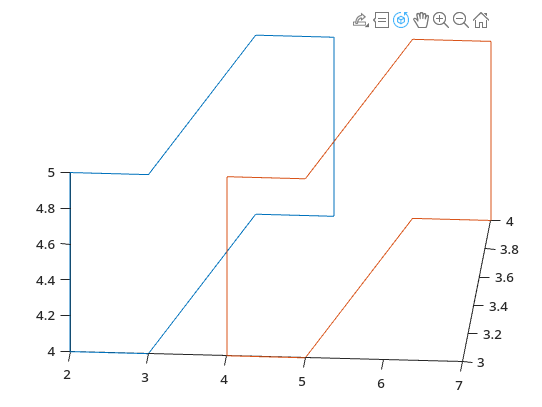

X = [2,3,4;3,3,4;4,4,4;5,4,4;5,4,5;4,4,5;3,3,5;2,3,5;2,3,4];
X = [X, ones(size(X,1),1)];
clf;
hold on;
plotObject(X)
Xp = translation(X, [2 0 0]);
plotObject(Xp)
hold off;

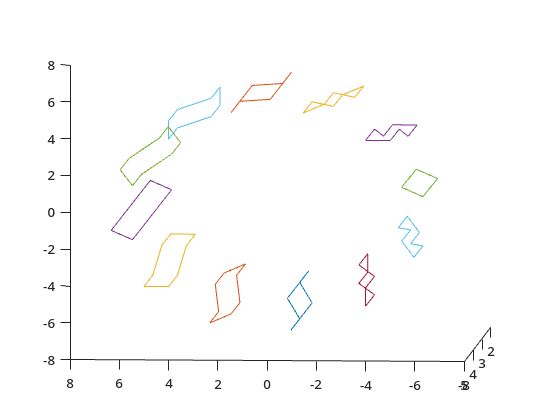

clf;
hold on;
Xp = X;
plotObject(Xp);
for i = 1:12
    Xp = (rotateX(Xp, (2*pi/12)));
    plotObject(Xp);
end
hold off;

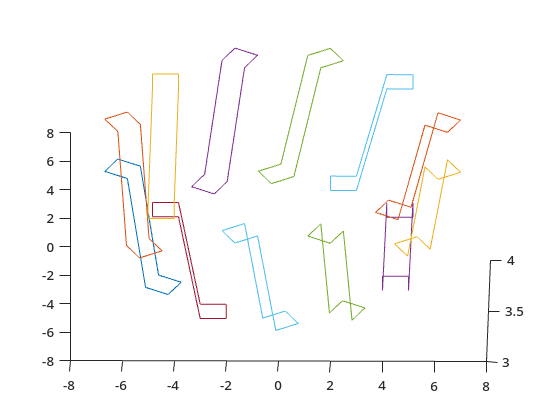

clf;
hold on;
Xp = X;
plotObject(Xp);
for i = 1:12
    Xp = (rotateY(Xp, (2*pi/12)));
    plotObject(Xp);
end
hold off;

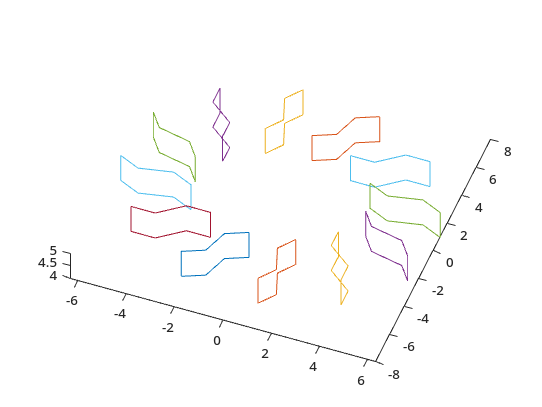

clf;
hold on;
Xp = X;
plotObject(Xp);
for i = 1:12
    Xp = (rotateZ(Xp, (2*pi/12)));
    plotObject(Xp);
end
hold off;

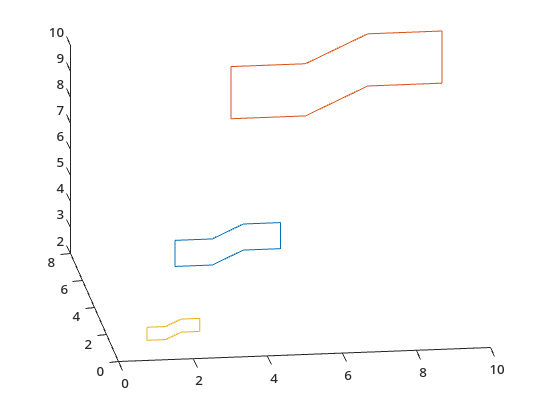

clf;
hold on;
plotObject(X);
plotObject(scale(X, 2));
plotObject(scale(X, 0.5));
hold off;

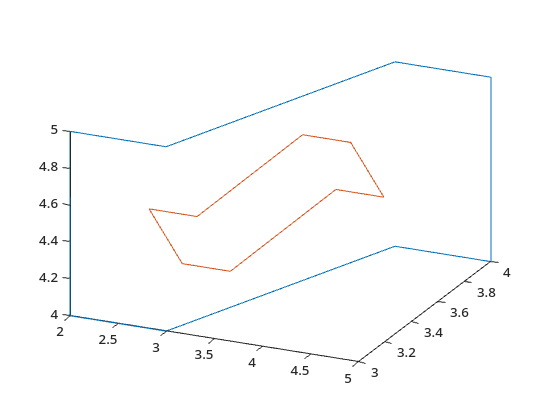

clf;
hold on;
c = mean(X);
Xp = X;
Xp = translation(Xp, -1*c);
Xp = scale(Xp, 0.5);
Xp = rotateX(Xp, 2*pi/12);
Xp = translation(Xp, c);
plotObject(X);
plotObject(Xp);
hold off;

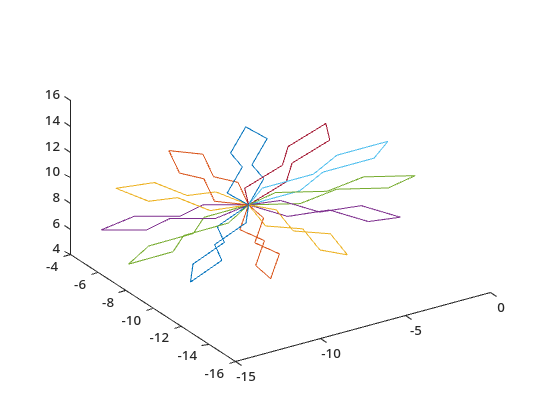

clf;
hold on;
a = [1, 1, 1];
u = [1, 0 0];
for i = 1:12
    plotObject(rotateU(X, a, u, (2*pi/12)*i));
end
hold off;

*Przydatne funkcje:*

plot3, transltform3d, rigidtform3d, simtform3d, invert, xline, rotvec2mat3d 

function plotObject(X)
    plot3(X(:, 1), X(:, 2), X(:, 3))
end

function [Xp] = translation(X, t)
    t_mat = eye(4);
    t_mat(4,1:3) = [t(1), t(2), t(3)];

    Xp = X * t_mat;
end

function [Xp] = rotateX(X, a)
    t_mat = eye(4);
    t_mat(2:3, 2:3) = [cos(a), sin(a); -1.*sin(a), cos(a)];
    
    Xp = X * t_mat;
end

function [Xp] = rotateY(X, a)
    t_mat = eye(4);
    t_mat(1:3, 1:3) = [cos(a), 0, -1*sin(a); 0, 1, 0 ; sin(a), 0, cos(a)];

    Xp = X * t_mat;
end

function [Xp] = rotateZ(X, a)
    t_mat = eye(4);
    t_mat(1:2, 1:2) = [cos(a), sin(a); -1.*sin(a), cos(a)];
    
    Xp = X * t_mat;
end

function [Xp] = scale(X, s)
    t_mat = eye(4);
    t_mat (1:3, 1:3) = eye(3)*s;

    Xp = X * t_mat;
end

function [Xp] = rotateU(X, a, u, o)
    d = sqrt(a(2)*a(2) + a(3)*a(3));
    Ra = eye(4);
    Ra(2:3, 2:3) = [a(3)/d, a(2)/d; -1*a(2)/d, a(3)/d];
    Rb = eye(4);
    Rb(1:3, 1:3) = [d, 0, a(1); 0, 1, 0; -1*a(1), 0, d];
    Rc = eye(4);
    Rc(1:2, 1:2) = [cos(o), sin(o); -1.*sin(o), cos(o)];
    Rt = eye(4);
    Rt(4,1:3) = [-1.*u(1), -1.*u(2), -1.*u(3)];
    
    Xp = X;
    Xp = Xp * Rt;
    Xp = Xp * Ra;
    Xp = Xp * Rb;
    Xp = Xp * Rc;
    Xp = Xp / inv(Rb);
    Xp = Xp / inv(Ra);
    Xp = Xp / Rt;
end